# SEIQR Model Simulation

Copyright 2022 Justice Inkoom at University of Mines and Technology

This is a simple **SEIQR** model of disease spread, implemented in MATLAB®. This approach is widely used to analyze infection data during the different stages of an epidemic outbreak. The population is divided into Susceptible (S), Exposed (E), Infectious (I), Quarantined (Q), and Recovered (R) individuals.

This particular model with its parameters are based on covid-19 outbreak in Ghana.

## The Model Overview

The equations that make up the SEIQR model are described by 5 ordinary differential equations as follows:


$$\begin{array}{l}
\frac{\textrm{ds}}{\textrm{dt}}=\alpha -\beta \ldotp s\ldotp \left(i+q\right)-\mu \ldotp s\\
\frac{\textrm{de}}{\textrm{dt}}=\beta \ldotp s\ldotp \left(i+q\right)-\left(\mu +\kappa +\gamma_2 +\nu \right)\ldotp e\\
\frac{\textrm{di}}{\textrm{dt}}=\kappa \ldotp e-\left(\mu +\delta_2 +\gamma_1 +\psi \right)\ldotp i\\
\frac{\textrm{dq}}{\textrm{dt}}=\nu \ldotp e+\psi \ldotp i-\left(\mu +\delta_1 +\gamma_3 \right)\ldotp q\\
\frac{\textrm{dr}}{\textrm{dt}}=\gamma_1 \ldotp i+\gamma_2 \ldotp e+\gamma_3 \ldotp q-\mu \ldotp r
\end{array}$$


## Model Simulation

**Model Parameters**

Play around with the parameters using the sliders and see the effect on the plot.

## Initial parameters

A = 1.5;
gamma = 0.01;
Beta = [0.00001,0.0001,0.004,0.008];
Beta_1 = 0.005;
k_1 = 0.005;
k = [3,5,10,15];
miu = [0.002,0.008,0.05,0.1];
B = [2,5,10,15];
b = [0.01,0.08,3,5];
b_1 = 0.001;


x0 = 5.0001;
y0 = 3.94;
z0 = 0.9231;
w0 = 4.0004;

**Solve the ODE using **[ode45](https://www.mathworks.com/help/matlab/ref/ode45.html).

L0 = [x0; y0; z0; w0];                % Initial conditions
L1 = [y0];
T = 4000;
tspan = [0 T];                        % Interval of Integration

% Changing values of miu
[t,y] = ode45(@(t,y) xyzw_model(t,y,A,gamma,Beta(1),Beta_1,k_1,k(1),miu(1),B(1),b(1),b_1),tspan,L0);
[t1,y1] = ode45(@(t1,y1) xyzw_model(t1,y1,A,gamma,Beta(1),Beta_1,k_1,k(1),miu(2),B(1),b(1),b_1),tspan,L0);
[t2,y2] = ode45(@(t2,y2) xyzw_model(t2,y2,A,gamma,Beta(1),Beta_1,k_1,k(1),miu(3),B(1),b(1),b_1),tspan,L0);
[t3,y3] = ode45(@(t3,y3) xyzw_model(t3,y3,A,gamma,Beta(1),Beta_1,k_1,k(1),miu(4),B(1),b(1),b_1),tspan,L0);

For more info see the [Anonymous functions documentation](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).

**Plots that show the results**

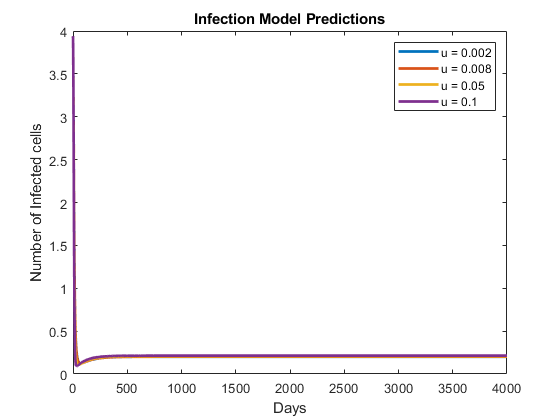

%% SIMULATION 3: CANCER CELLS WITH CHANGING VALUES OF MIU
%plot(t,y,'LineWidth',2);
plot(t,y(:,2),'LineWidth',2);
xlabel('Days'); 
ylabel('Number of Infected cells');
%title('XYZW Model Predictions');
title('Infection Model Predictions')
hold on
plot(t1,y1(:,2),'LineWidth',2);
plot(t2,y2(:,2),'LineWidth',2);
plot(t3,y3(:,2),'LineWidth',2);
hold off
%legend('k = 3','k = 5','k = 10','k = 15');
legend('u = 0.002','u = 0.008','u = 0.05','u = 0.1')

For more info see the [plot documentation](https://www.mathworks.com/help/matlab/ref/plot.html).

**Function **`seir_model`** that calculates the model evolution over a time period T.**

function dydt = xyzw_model(t,y,A,gamma,Beta,Beta_1,k_1,k,miu,B,b,b_1)
  X = y(1);
  Y = y(2);
  Z = y(3);
  W = y(4);
  % Equations of the model described above
  dX = (A-(gamma*X)-(Beta*X*Z)) ;
  dY = ((Beta*X*Z)-(gamma*Y)-(Beta_1*Y*Z)) ; 
  dZ = (k+(miu*Z)-(gamma*Z)-(k_1*Z*W)) ;
  dW = (B+(b*Z)-(gamma*W)-(b_1*W*Z));
  dydt = [dX;dY;dZ;dW];
end

## Further Evaluation

The three critical parameters in the model are beta, lambda and gamma.

Note that we have left several features unmodeled, for example: 

- Immunity loss rate ($\left.\alpha \right)$, where recovered individuals can get infected again.

- Some exposed individuals in "E" might move directly to the "R" category;

-  Some infected individuals in category "I" might not gain perfect immunity and so may move back to susceptible category "S." 

Despite these limitations, this basic SEIR model can provide some useful insights on the disease evolution.

  **Task.** Include additional features to your model and observe the effect on the plot.

                Example: To include Immunity loss rate ($\left.\alpha \right)$, the equations will be as follows:

                
$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \frac{I}{N}+\alpha \cdot \mathrm{R}\\
\frac{\textrm{dE}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \frac{I}{N}-\lambda \cdot E\\
\frac{\textrm{dI}}{\textrm{dt}}=\lambda \cdot E-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\alpha \cdot \mathrm{R}
\end{array}$$
